**Author: Clara Vetter**

**Last modified: 15.01.2024**

addpath("~/local/Code/mSPLS/ScrFun/")

# Test script for multiblock spls with simulated data

This script tests and compares different multiblock sPLS implementations. 

- cv_mbSPLS(): this is the function proposed by ChatGPT/ David including minor changes (fixed bugs). 

- cv_multiview_spls(): alternative approach for three input data matrices (approach similar to Tenenhaus (2011, Regularized Generalized CCA, DOI:10.1007/S11336-011-9206-8) 

- cv_generalized_spls(): this is a generalized version of sPLS using the similar to the approach used in Tenenhaus (2011, Regularized Generalized CCA, DOI:10.1007/S11336-011-9206-8); similar to 2. but can handle a flexible amount of data matrices. 

## Simulated data

rng(42);

% Number of samples and features
numSamples = 100;
numFeaturesX = 50;
numFeaturesY = 200;
numFeaturesZ = 30;

% Generate random data matrices X, Y, Z
X = randn(numSamples, numFeaturesX);
Y = randn(numSamples, numFeaturesY);
Z = randn(numSamples, numFeaturesZ);

## Define sPLS parameters

% Sparsity regularization parameters
cu = 5;
cv = 5;
cw = 5;
% Convergence threshold and iteration limit
e = 1e-5;
itr_lim = 1000;

## cv_mbSPLS

This function actually performs separate sPLS between the matrices in X_multi and Z, respectively. This means, the relationship between X_multi's are not considered. Also, this is effectively not a multiblock sPLS approach, as the updating of weights happens separately for each pair of X_multi matrices wit Z. 

X_multi{1} = X;
X_multi{2} = Y; 

cu_multi{1} = cu; 
cu_multi{2} = cv;
[u_multi, w, success] = cv_mbSPLS(X_multi, Z, cu_multi, cw, e, itr_lim);

MB-SPLS: itr: 43    diff: 8.63e-06


Comparing the output to pairwise sPLS using the spls() function, shows that the results are exactly the same for the respective pairs XZ and YZ. 

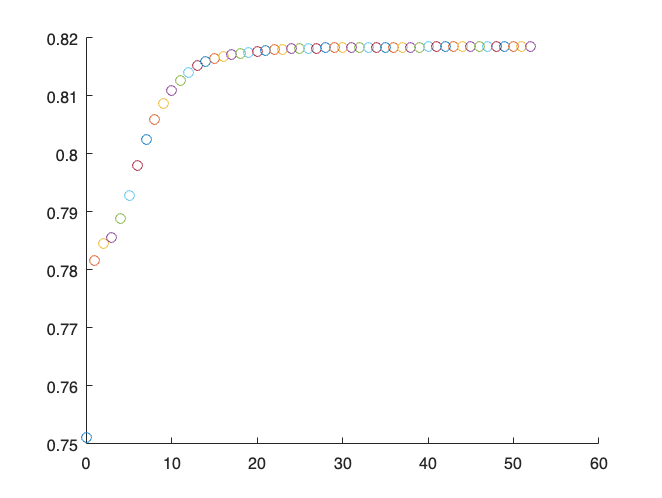

SPLS: itr: 53    diff: 9.84e-06    dim_u: 44    dim_v: 42


% sPLS: X & Y
[u, v, success] = cv_spls(X, Y, cu, cv, e, itr_lim);


corr(u, u_multi{1})

ans = -0.1582

corr(v, u_multi{2})

ans = 0.0884

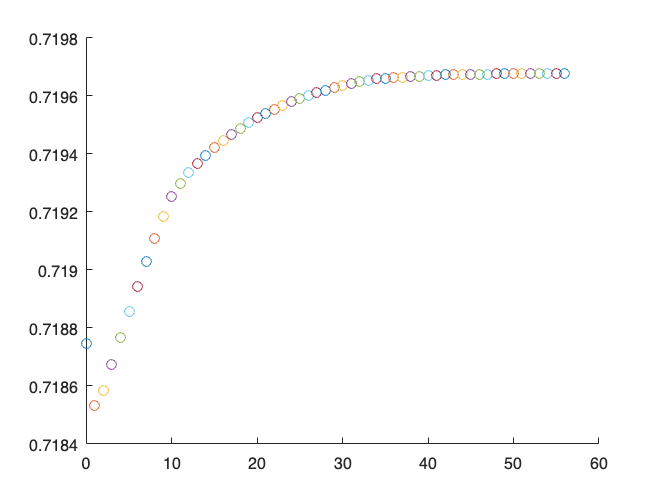

SPLS: itr: 57    diff: 9.51e-06    dim_u: 40    dim_v: 30



% sPLS: X & Z
[u1, w1, success] = cv_spls(X, Z, cu, cw, e, itr_lim);


corr(u1, u_multi{1})

ans = 1.0000

corr(w1, w{1})

ans = 1.0000

isequal(u1, u_multi{1})

ans = logical
   1


isequal(w1, w{1})

ans = logical
   1


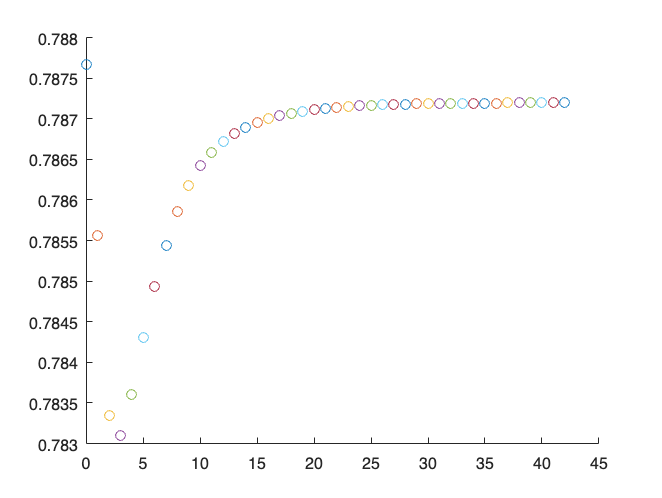

SPLS: itr: 43    diff: 8.63e-06    dim_u: 39    dim_v: 30



% sPLS: Y & Z
[v2, w2, success] = cv_spls(Y, Z, cv, cw, e, itr_lim);


corr(v2, u_multi{2})

ans = 1.0000

corr(w2, w{2})

ans = 1.0000


isequal(v2, u_multi{2})

ans = logical
   1


isequal(w2, w{2})

ans = logical
   1


## cv_multiblock_spls

% Call the spls3 function
[u3, v3, w3, success] = cv_multiview_spls(X, Y, Z, cu, cv, cw, e, itr_lim);

SPLS: itr: 69    diff: 9.82e-06    dim_u: 38    dim_v: 38    dim_w: 30


% pairwise sPLS X & Y vs. cv_multiview_spls
corr(u, u3)

ans = 0.7100

corr(v, v3)

ans = 0.5486


% pairwise sPLS X & Z vs. cv_multiview_spls
corr(u1, u3)

ans = -0.5139

corr(w1, w3)

ans = -0.5743


% pairwise sPLS Y & Z vs. cv_multiview_spls
corr(v2, v3)

ans = 0.1672

corr(w2, w3)

ans = 0.4757


% cv_mbSPLS vs. cv_multiview_spls
corr(u_multi{1},u3)

ans = -0.5139

corr(u_multi{2},v3)

ans = 0.1672

corr(w{1}, w3)

ans = -0.5743

corr(w{2}, w3)

ans = 0.4757

## cv_generalized_spls

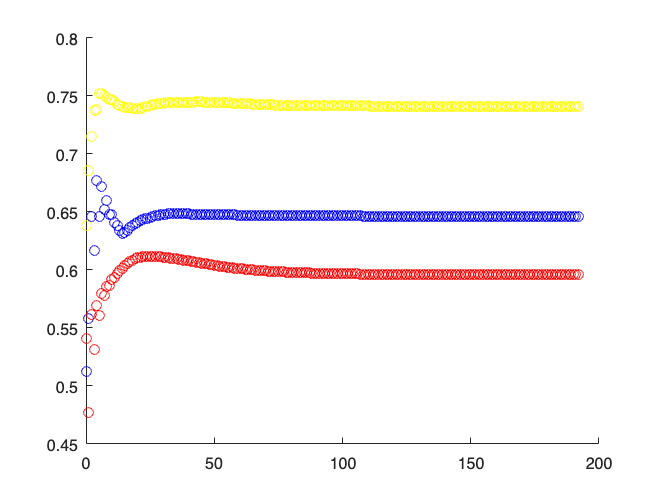

SPLS: itr: 193    diff: 9.71e-06    dim_M1: 41    dim_M2: 38    dim_M3: 30    


matrices{1} = X;
matrices{2} = Y;
matrices{3} = Z;

cs = [cu, cv, cw];
num_matrices = 3;
% Design matrix to model relationship between matrices: Equal influence between matrices 
gs = (1/(num_matrices-1)) * (ones(num_matrices) - eye(num_matrices));

% Run generalized SPLS
[weights, covariances, success] = cv_generalized_spls(matrices, cs, gs, e, itr_lim);

% pairwise sPLS X & Y vs. cv_generalized_spls
corr(u, weights{1})

ans = 0.6834

corr(v, weights{2})

ans = 0.5380


% pairwise sPLS X & Z vs. cv_generalized_spls
corr(u1, weights{1})

ans = -0.5905

corr(w1, weights{3})

ans = -0.6228


% pairwise sPLS Y & Z vs. cv_generalized_spls
corr(v2, weights{2})

ans = 0.2153

corr(w2, weights{3})

ans = 0.5366


% cv_mbSPLS vs. cv_generalized_spls
corr(u_multi{1}, weights{1})

ans = -0.5905

corr(u_multi{2}, weights{2})

ans = 0.2153

corr(w{1}, weights{3})

ans = -0.6228

corr(w{2}, weights{3})

ans = 0.5366


% cv_multiview_spls vs. cv_generalized_spls
corr(u3, weights{1})

ans = 0.9867

corr(v3, weights{2})

ans = 0.9796

corr(w3, weights{3})

ans = 0.9906

## Next/ open questions/ to discuss

### cv_generalized_spls

- check normalization - when ? in each pairwise update or only after it's joined together? 

- does the updating make sense like this? 

### permutation testing for component significance

- pairwise correlations; only if all significant? 

- different option? 